Projekt 13: ***Wyznaczanie kadencji biegowej na podstawie sygnałów akcelerometrycznych, z  wykorzystaniem funkcji autokorelacji***

Wyznaczanie chwilowej kadencji biegowej/chodu (liczby kroków na minutę) na podstawie  sygnałów przyspieszeń ciała przy pomocy funkcji autokorelacji. Należy zastosować techniki zwiększające rozdzielczość wyznaczania przebiegu kadencji. 

Załadowanie danych projektowych

load sensorlog_20220307_165621.mat

x = Acceleration.X;
y = Acceleration.Y;
z = Acceleration.Z;
timestamp = Acceleration.Timestamp;

% obliczenie różnicy czasowej między próbkami w [s] i częstotliwości
% próbkowania fs [Hz]
dt = seconds(diff(timestamp));
mean_dt = sum(dt)/length(dt);
fs = 1 / mean_dt;
fprintf('Częstotliwość próbkowania wynosi: %.2f Hz', fs)

Częstotliwość próbkowania wynosi: 52.63 Hz

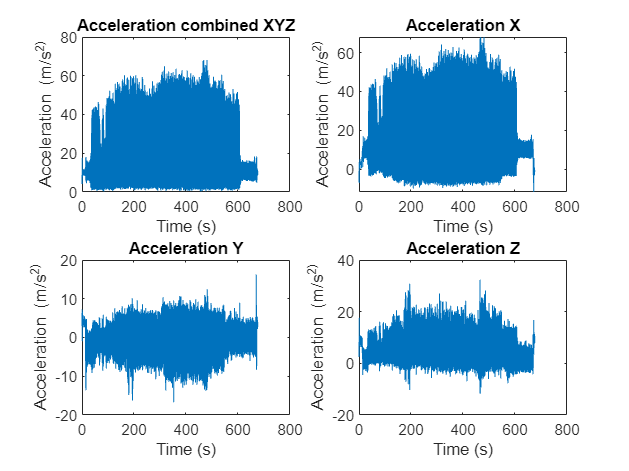


combinedAccel = sqrt(x.^2+y.^2+z.^2);
t = zeros(size(timestamp));


for n = 1 : length(timestamp)
  t(n) = seconds(timestamp(n) - timestamp(1));
end

figure,
subplot(2, 2, 1)
plot(t, combinedAccel)
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
title('Acceleration combined XYZ')

subplot(2, 2, 2)
plot (t,x)
title('Acceleration X')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

subplot(2, 2, 3)
plot (t,y)
title('Acceleration Y')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

subplot(2, 2, 4)
plot (t,z)
title('Acceleration Z')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

Spektrogram

% Lenght of window
min = log2(16);
max = log2(1024);
window = 2^9

window = 512

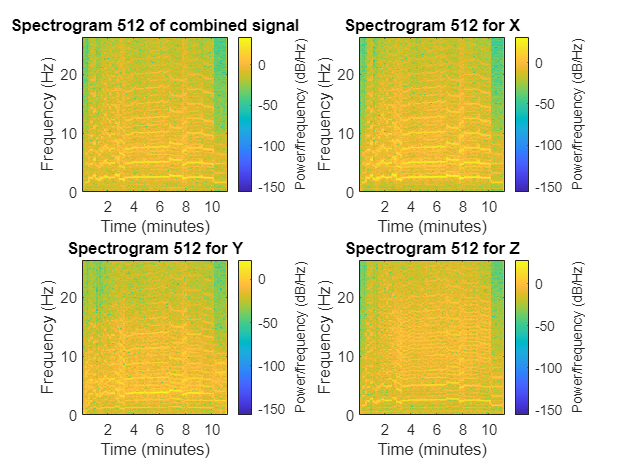

noverlap = int8(0.7*window);
nfft = 1024;
fs1 = fs;
figure,
subplot(2, 2, 1)
spectrogram(combinedAccel, window, noverlap, nfft,fs1,'yaxis');  
title(sprintf("Spectrogram %i of combined signal", window))
subplot(2, 2, 2)
spectrogram(x, window, noverlap, nfft,fs1,'yaxis');  
title(sprintf("Spectrogram %i for X", window))
subplot(2, 2, 3)
spectrogram(y, window, noverlap, nfft,fs1,'yaxis');  
title(sprintf("Spectrogram %i for Y", window))
subplot(2, 2, 4)
spectrogram(z, window, noverlap, nfft,fs1,'yaxis');  
title(sprintf("Spectrogram %i for Z", window))

Autocorrelation

autocorr_x = xcorr(x);

Unrecognized function or variable 'x'.

figure;
plot(autocorr_x);
title('Autocorrelation for X');
xlabel('Delay');
ylabel('Autocorrelation values');



Autokorelacja z przebiegów x lub z combined.

Dopasowanie okna autokorelacji (nie za długie, żeby nie wykrywało kilku kroków)

Zakres kadencji przyjąć 60-300 (średnia około 170-200, rekord świata 380)

Filtracja - dopasowana do zakresu kadencji 

 min_cadence = 60
 min_fs = 60/60
 max_cadence = 300
 max_fs = 300/60
